Run graphics export and animation from the Command Window; Live Editor export can block. Run runMeFirst in the package root, then add the chosen example folder or make it Current Folder before calling a .m example by name.

# gearsInMesh — Mating pair (v21)

gears v21 — Public interface guide.

Run runMeFirst once from the package root before running this Live Script. The bundled draw*/gk* routines and int2crv are private implementation helpers in classes/private; do not add that folder to the MATLAB path.

See examples/README.md for the scripts. Relative outputs use Current Folder; output methods create missing parent folders. Cached Live Script outputs are retained from the supplied archive and have not been regenerated. Run sections in order for current results.

Use public plot/animate/print methods. For plots: 'title',on/off/1/0/true/false; 'save',filename or 'save',[] for the default JPG. Names without '-' are preferred; the old prefix remains accepted.

A handle object assembled from compatible gear objects. Each source gear keeps its own x and u; the basic rack remains unchanged.

## Syntax

gearsInMesh(g1,g2)

## **Description**

gearsInMesh(g1,g2) assembles two existing gear handles for parallel-axis, zero-backlash geometry.

## Input arguments

g1,g2 - gear objects with equal normal module and pressure angle; use equal nonnegative helix-angle magnitudes. gear3d assigns opposite hands to the displayed pair.

## **Properties**

**G1, G2 - gear objects**

**a    - center distance**

alphaw - working transverse pressure angle in degrees. cw is the minimum radial tip/root clearance in length units; Rw1/Rw2 are working pitch radii.

# Object functions

## plot

draw gears in mesh

### Syntax

plot(GM)  draw gears GM.G1 and GM.G2  in mesh

plot(__,'th1',th1) specify initial rotation angle th1 of the first gear GM.G1.

plot(__,'zoom',fac) specify zoom factor fac in units of module.

plot(__,'a',a) overrides the displayed centre distance only; it does not change GM.a.

plot(__,'np',np) sets contour sampling density, not the total vertex count.

### Input arguments

**GM - gearsInMesh object**

### Optional input arguments

**'save',filename or 'save',[] - named/default JPG; 'title',false hides the title**

### Optional name-value input arguments

'a',a - displayed centre distance; default GM.a. It is a local drawing override.

'np',np - contour sampling control, integer 4..100; default 20.

**'th1',th1  - initial rotation angle in degrees of gear g1. Default value is 0. **

'zoom',fac - 0 for the full view (default), or fac>=2 for a window with half-width fac*m centred at (GM.G1.Rr,0).

## animate

draw successive positions of gears in mesh

### Syntax

animate(GM)  animate gears GM.G1 and GM.G2  in mesh

animate(__,'dth1',dth1) specify step of rotation angle dth1 of the first gear GM.G1.

animate(__,'zoom',fac) specify zoom factor fac in units of module.

animate(__,'a',a) overrides the displayed centre distance; it does not change GM.a.

animate(__,'np',np) sets contour sampling density.

animate(__,'nr',nr) specify number of turns of gear 1

### Input arguments

**GM - gearsInMesh object**

### Optional input arguments

**'save',filename or 'save',[] - named/default AVI; use 'snapshot',stem for P-key JPG images**

### Optional name-value input arguments

'a',a - displayed centre distance; default GM.a. It does not recompute pair properties.

**'nr',nr - number of automatic rotations of gear 1; default 1, ignored in interactive mode.**

'np',np - contour sampling control, integer 4..100; default 20.

**'dth1',dth1  - step of rotation angle in degrees of gear GM.G1. Default value is 1 degree. **

'zoom',fac - 0 for the full view (default), or fac>=2 for a close-up centred at (GM.G1.Rr,0).

## Current animation and output interface

animate(GM,'mode','interactive','figureSize',[1000 700],'contactPoints',true,'snapshot','figures/doc/pair')

L/D step forward/backward; P saves the current JPG; Esc finishes; H repeats help. Space pauses automatic playback. instructions/echo controls informational output. figureSize in this 2-D animator takes 2 or 4 values, not a scalar.

Lc and epsalpha are nominal tip-circle values. Contact markers use retained involutes and do not certify interference clearance or tooth-root strength.

print(GM,fid) and printOptimization(GM,fid) use an open text-file identifier. printOptimization reports stored data only; this archive has no optimisation routine. gear3d(GM) provides 3-D views and animation; see examples/3d.

## Examples

% Run runMeFirst once before this Live Script; private helpers are bundled.

% Outputs use pwd. No output directories are created by setup.
assert(~isempty(which('gear')),'Run runMeFirst first.');


### Example1

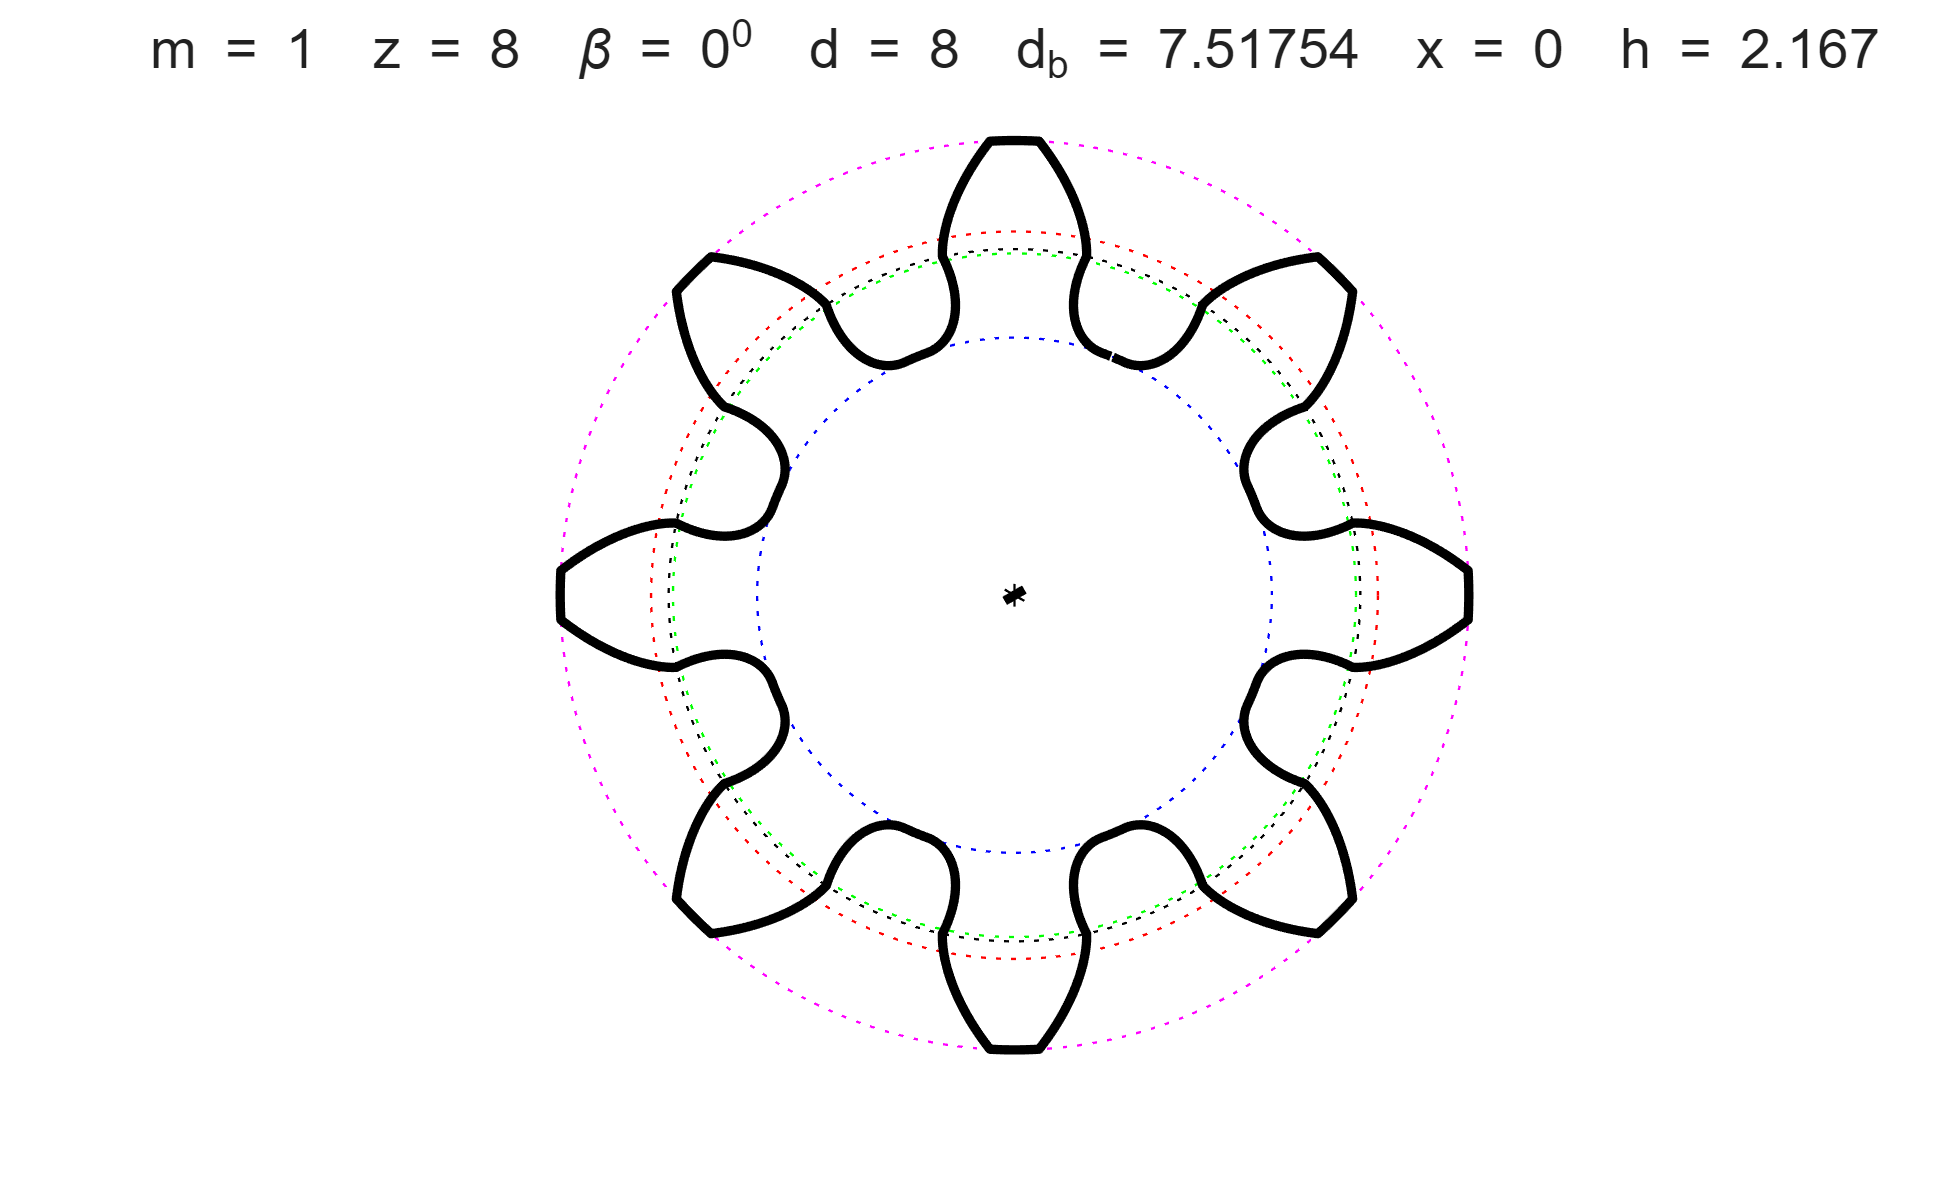

% define gear rack with module 1mm
a = gearRack(1);
% define 8-tooth and 52-tooth gears
G1 = gear(a,8);
G2 = gear(a,52);
% plot gears
plot(G1)

print(G1)

Data
                               Number of teeth:           8
                                        Module:      1.0000 mm
                       Standard pressure angle:    20:00:00 
             Manufacturing tip tooth clearance:      0.1670 mm
                The tip shortening coefficient:      1.0000 
                                   Helix angle:     0:00:00 
                    Profile shift coefficients:      0.0000
Calculated parameters
                Addendum (tip) circle diameter:     10.0000 mm
               Reference pitch circle diameter:      8.0000 mm
                      Undercut circle diameter:      7.6126 mm
                          Base circle diameter:      7.5175 mm
               Dedendum (root) circle diameter:      5.6660 mm
                            Total tooth height:      2.1670 mm
                         Addendum tooth height:      1.0000 mm
                         Dedendum tooth height:      0.1937 mm
        Tooth thickness at the addendum 

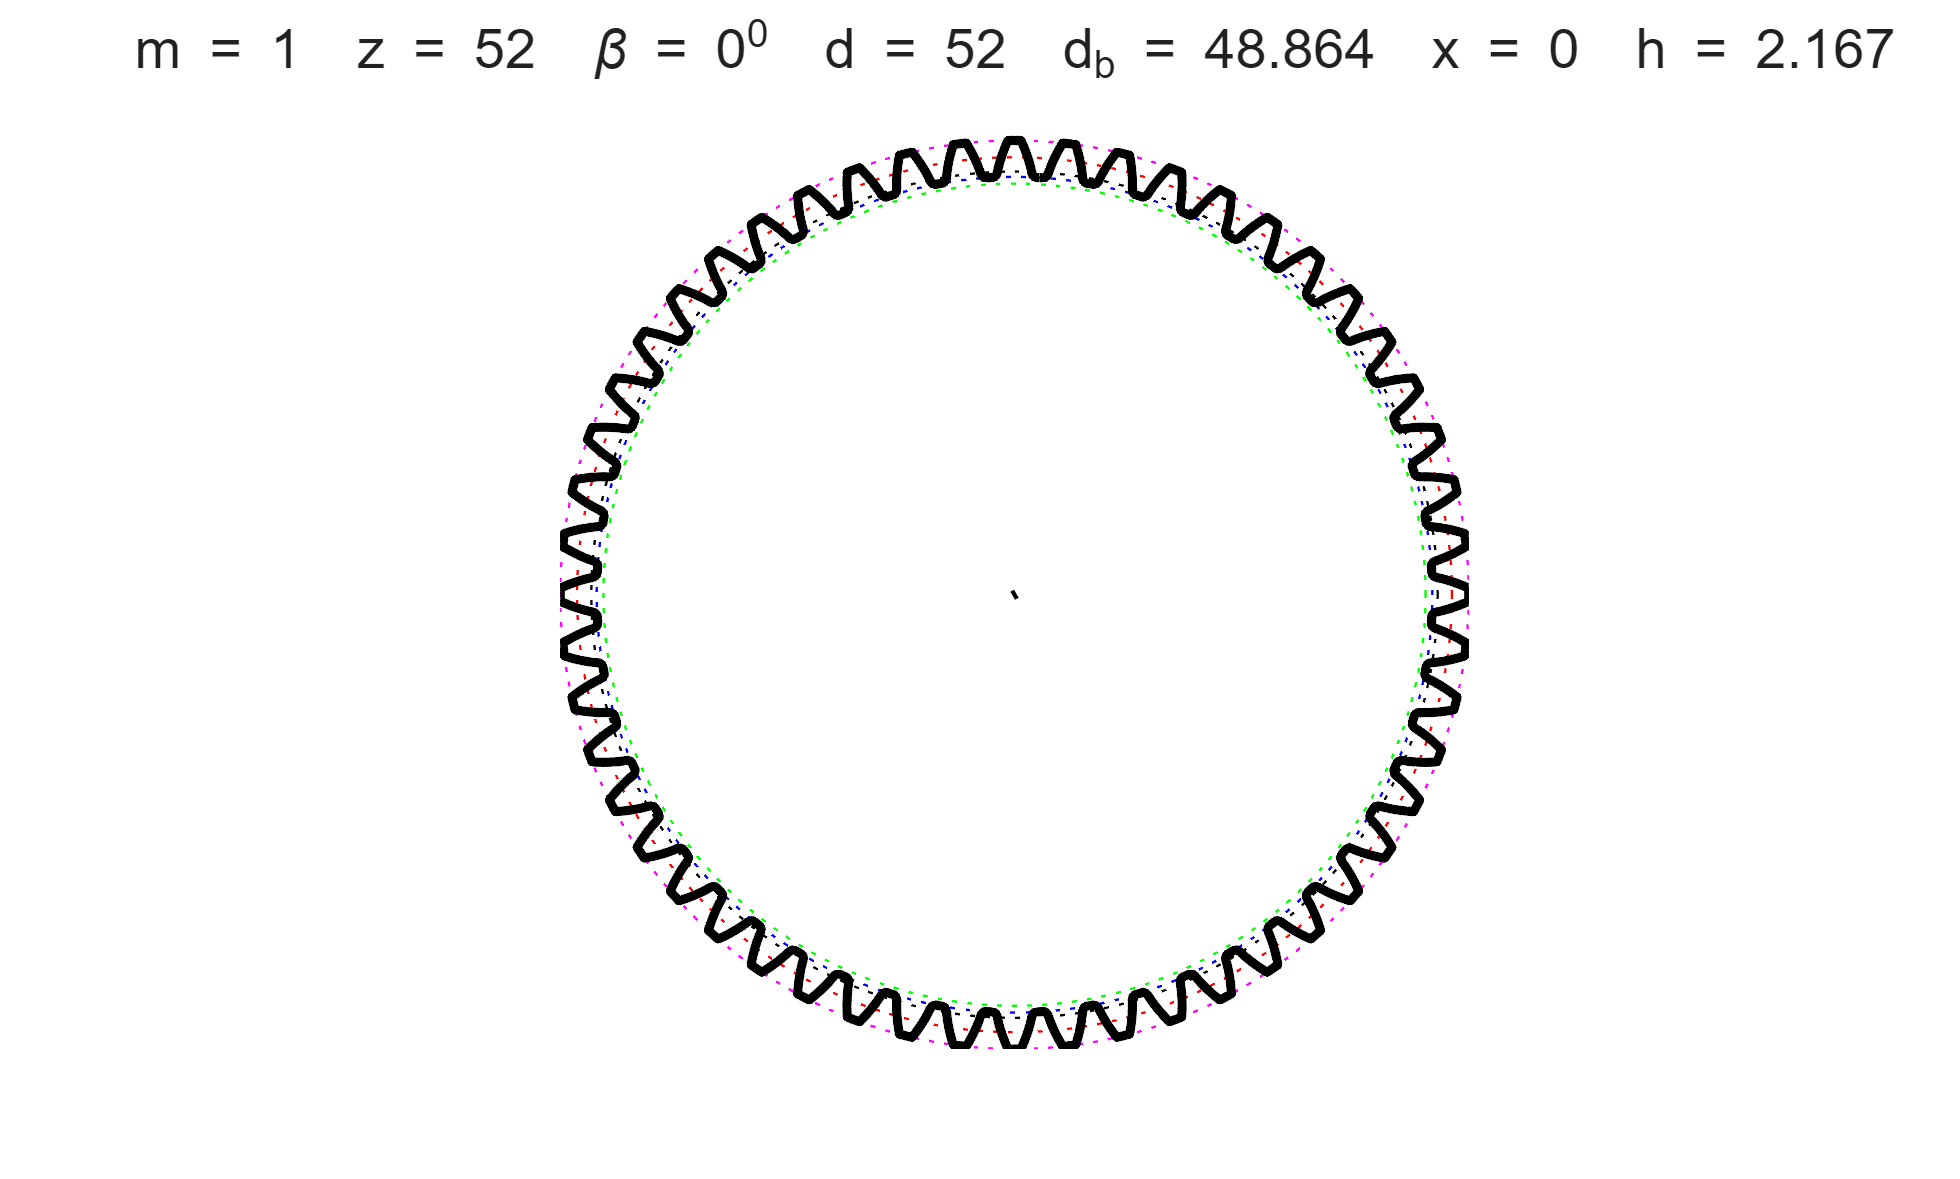

plot(G2)

% create gears in mesh
GM=gearsInMesh(G1,G2) 

GM =   gearsInMesh with properties:

                  G1: [1×1 gear]
                  G2: [1×1 gear]
    optimizationInfo: [0×0 struct]
                   a: 30
              alphaw: 20
                  cw: 0.1670
                 Rw1: 4
                 Rw2: 26
                  Lc: 4.5291
            epsalpha: 1.5342
             invalid: 0


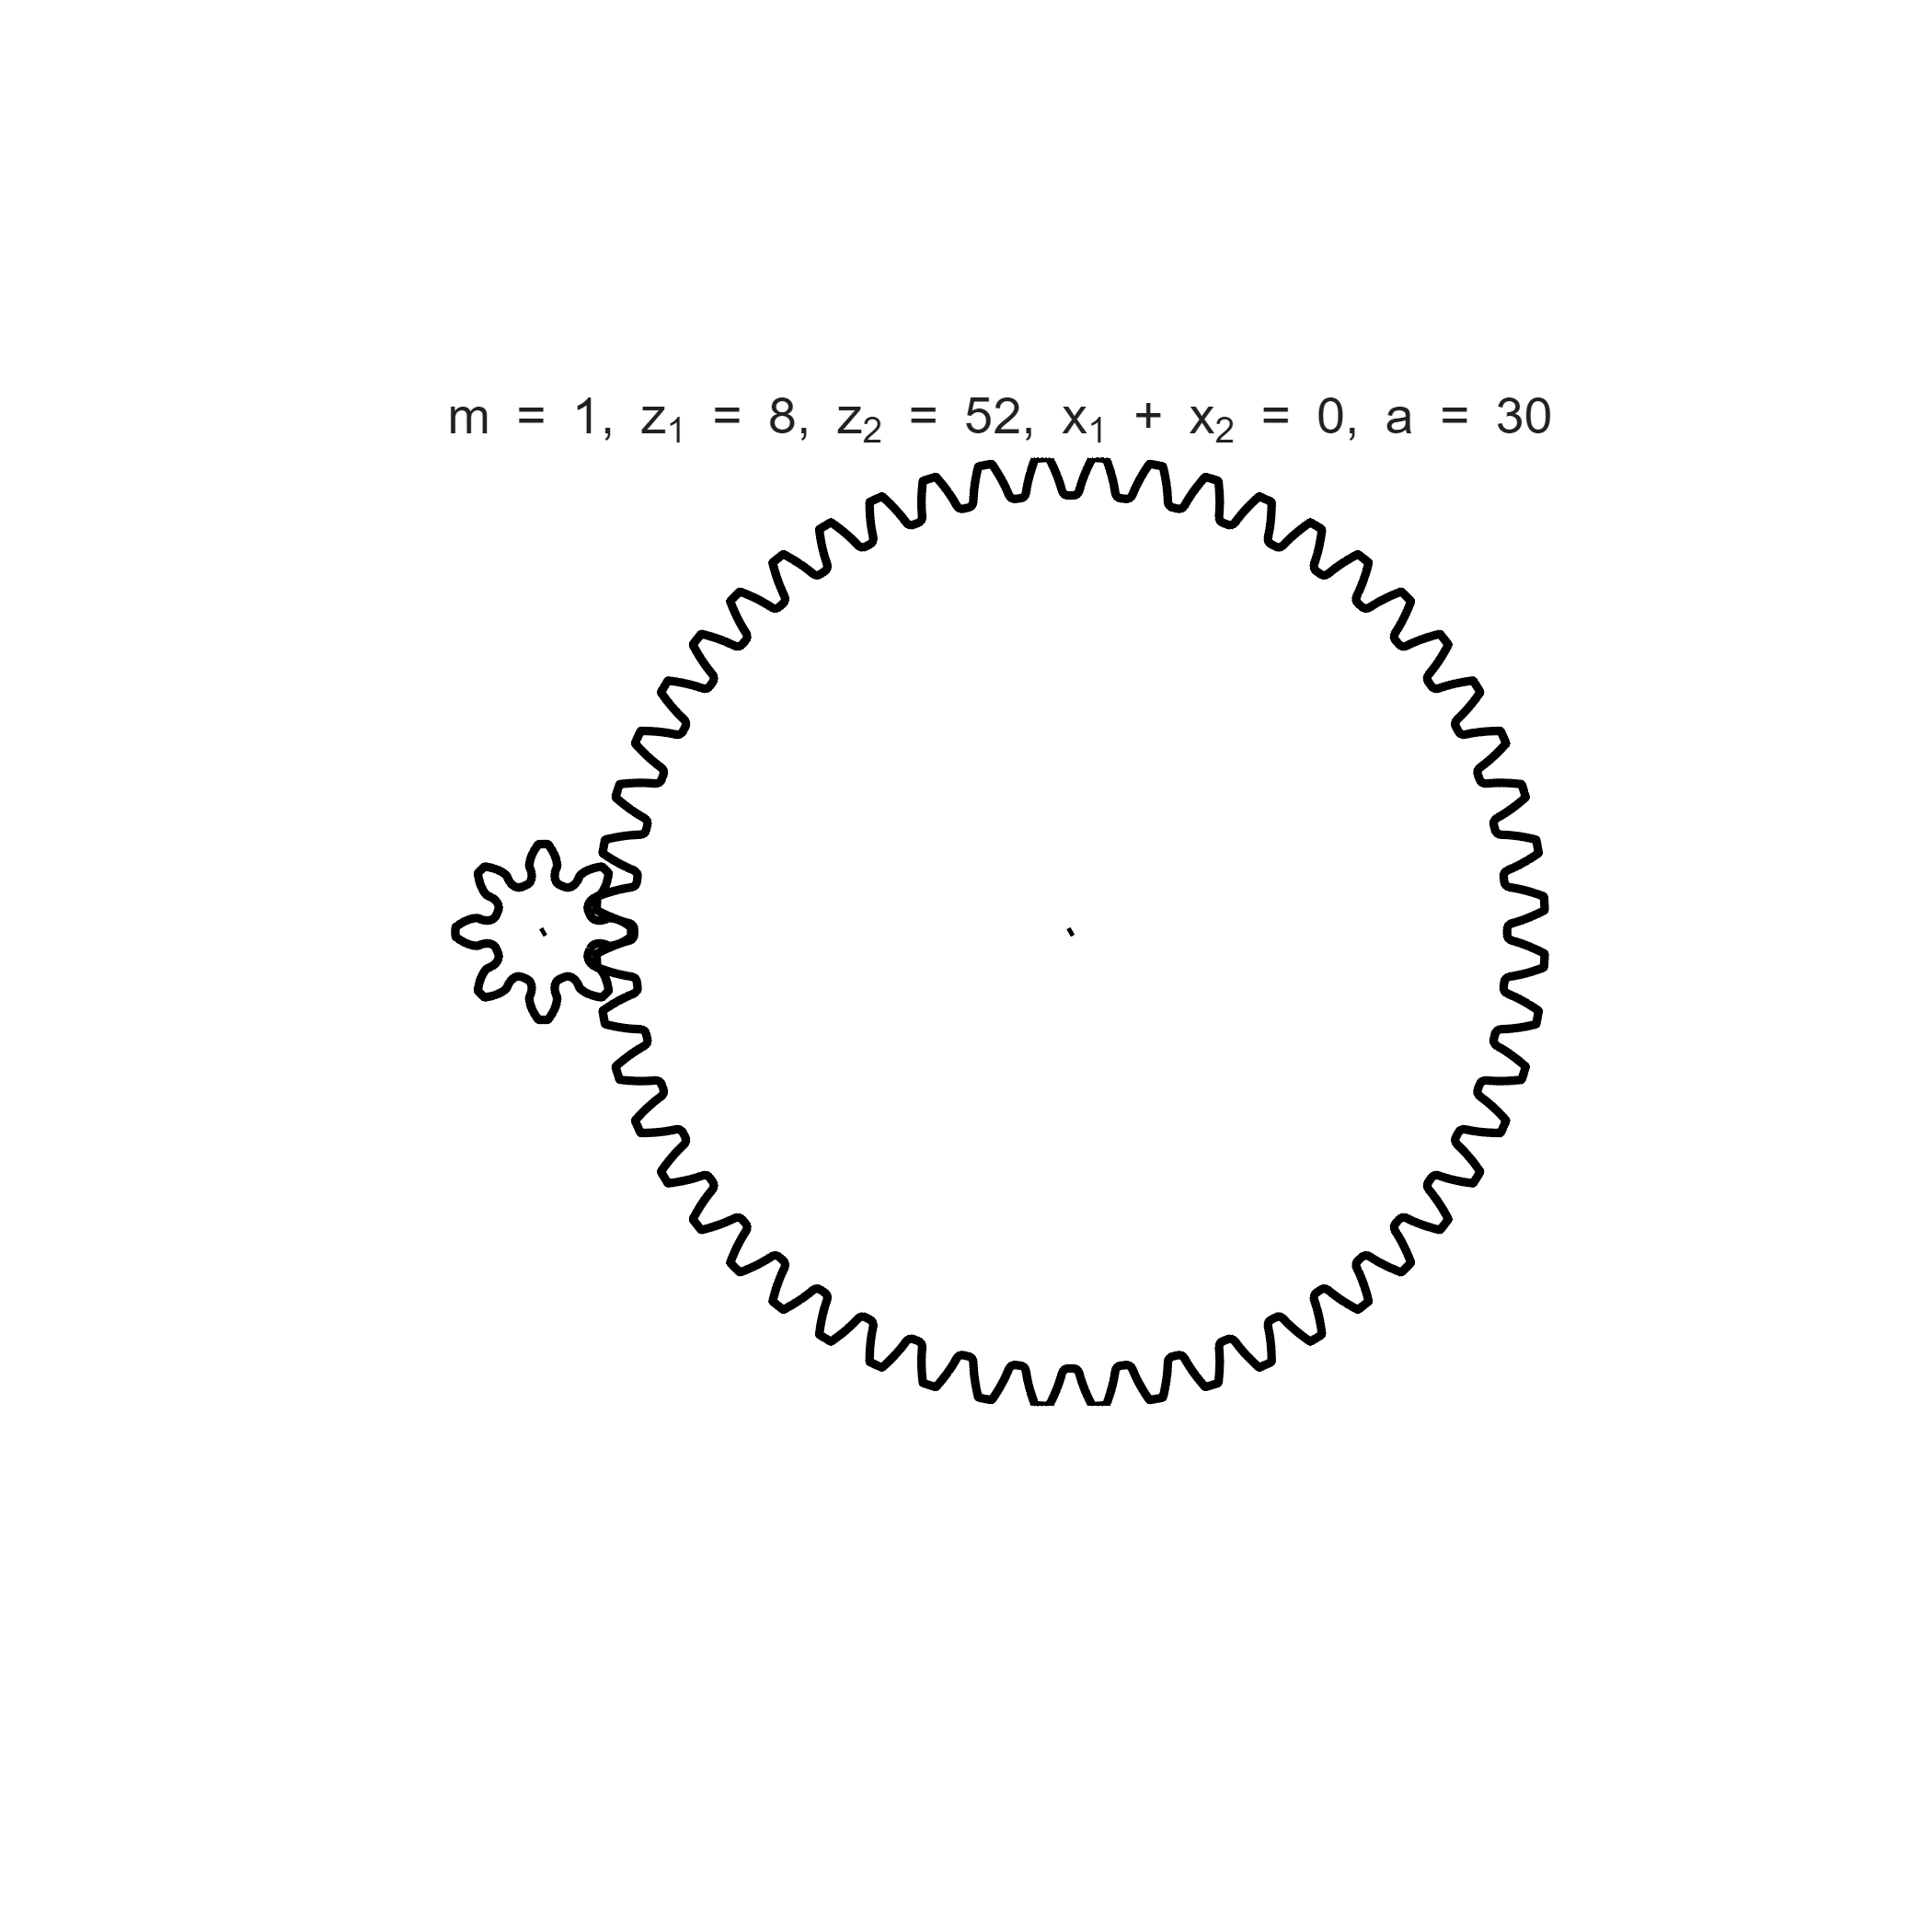

% plot gears
plot(GM)

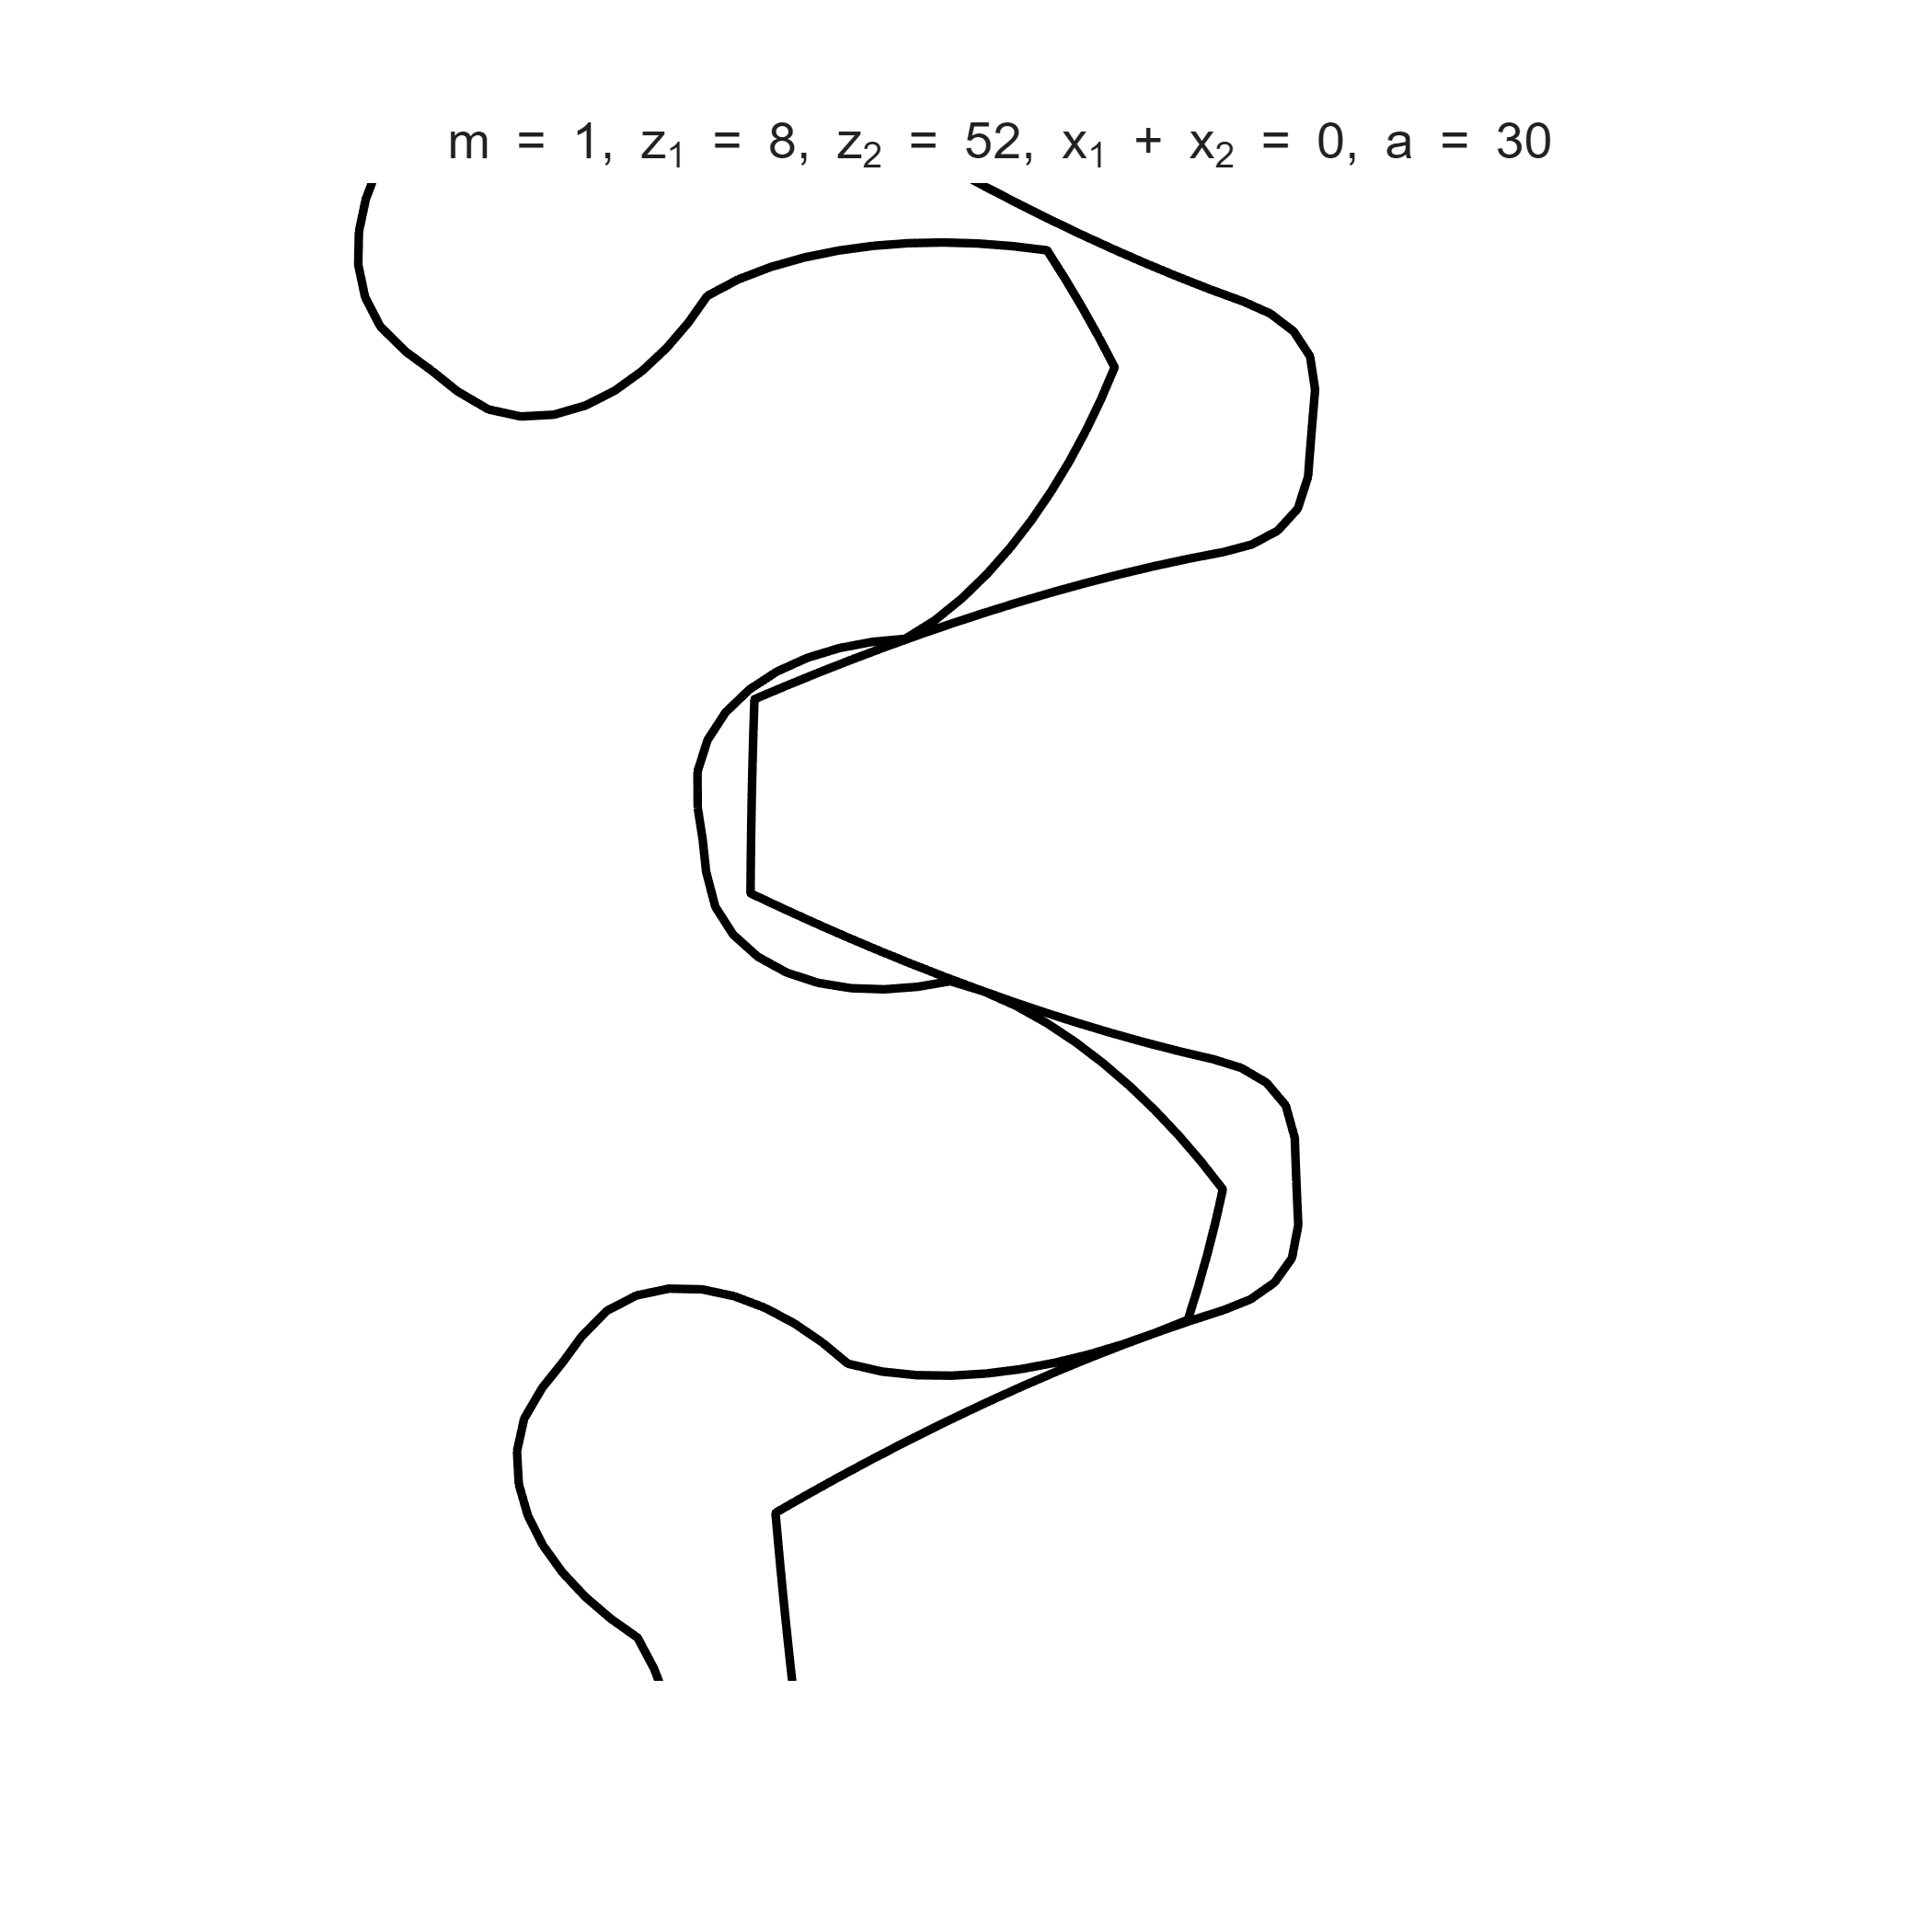

% zoom contact zone within 3 module and rotate gear 1 by 30 deg
plot(GM,'th1',30,'zoom',3)

% print
print(GM)


Gears in mesh
                               Number of teeth:           8          52
                                        Module:            1.0000       mm
                       Standard pressure angle:           20.0000       
                           Tip tooth clearance:            0.1670       mm
                               Center distance:           30.0000       
                    Tip shortening coefficient:      1.0000      1.0000
                        Working pressure angle:           20.0000       
         Sum of the profile shift coefficients:            0.0000       
                    Profile shift coefficients:      0.0000      0.0000
Calculated parameters
               Reference pitch circle diameter:      8.0000     52.0000 mm
                 Working pitch circle diameter:      8.0000     52.0000 mm
                      Addendum circle diameter:     10.0000     54.0000 mm
                      Dedendum circle diameter:      5.6660     49.6660 mm
     

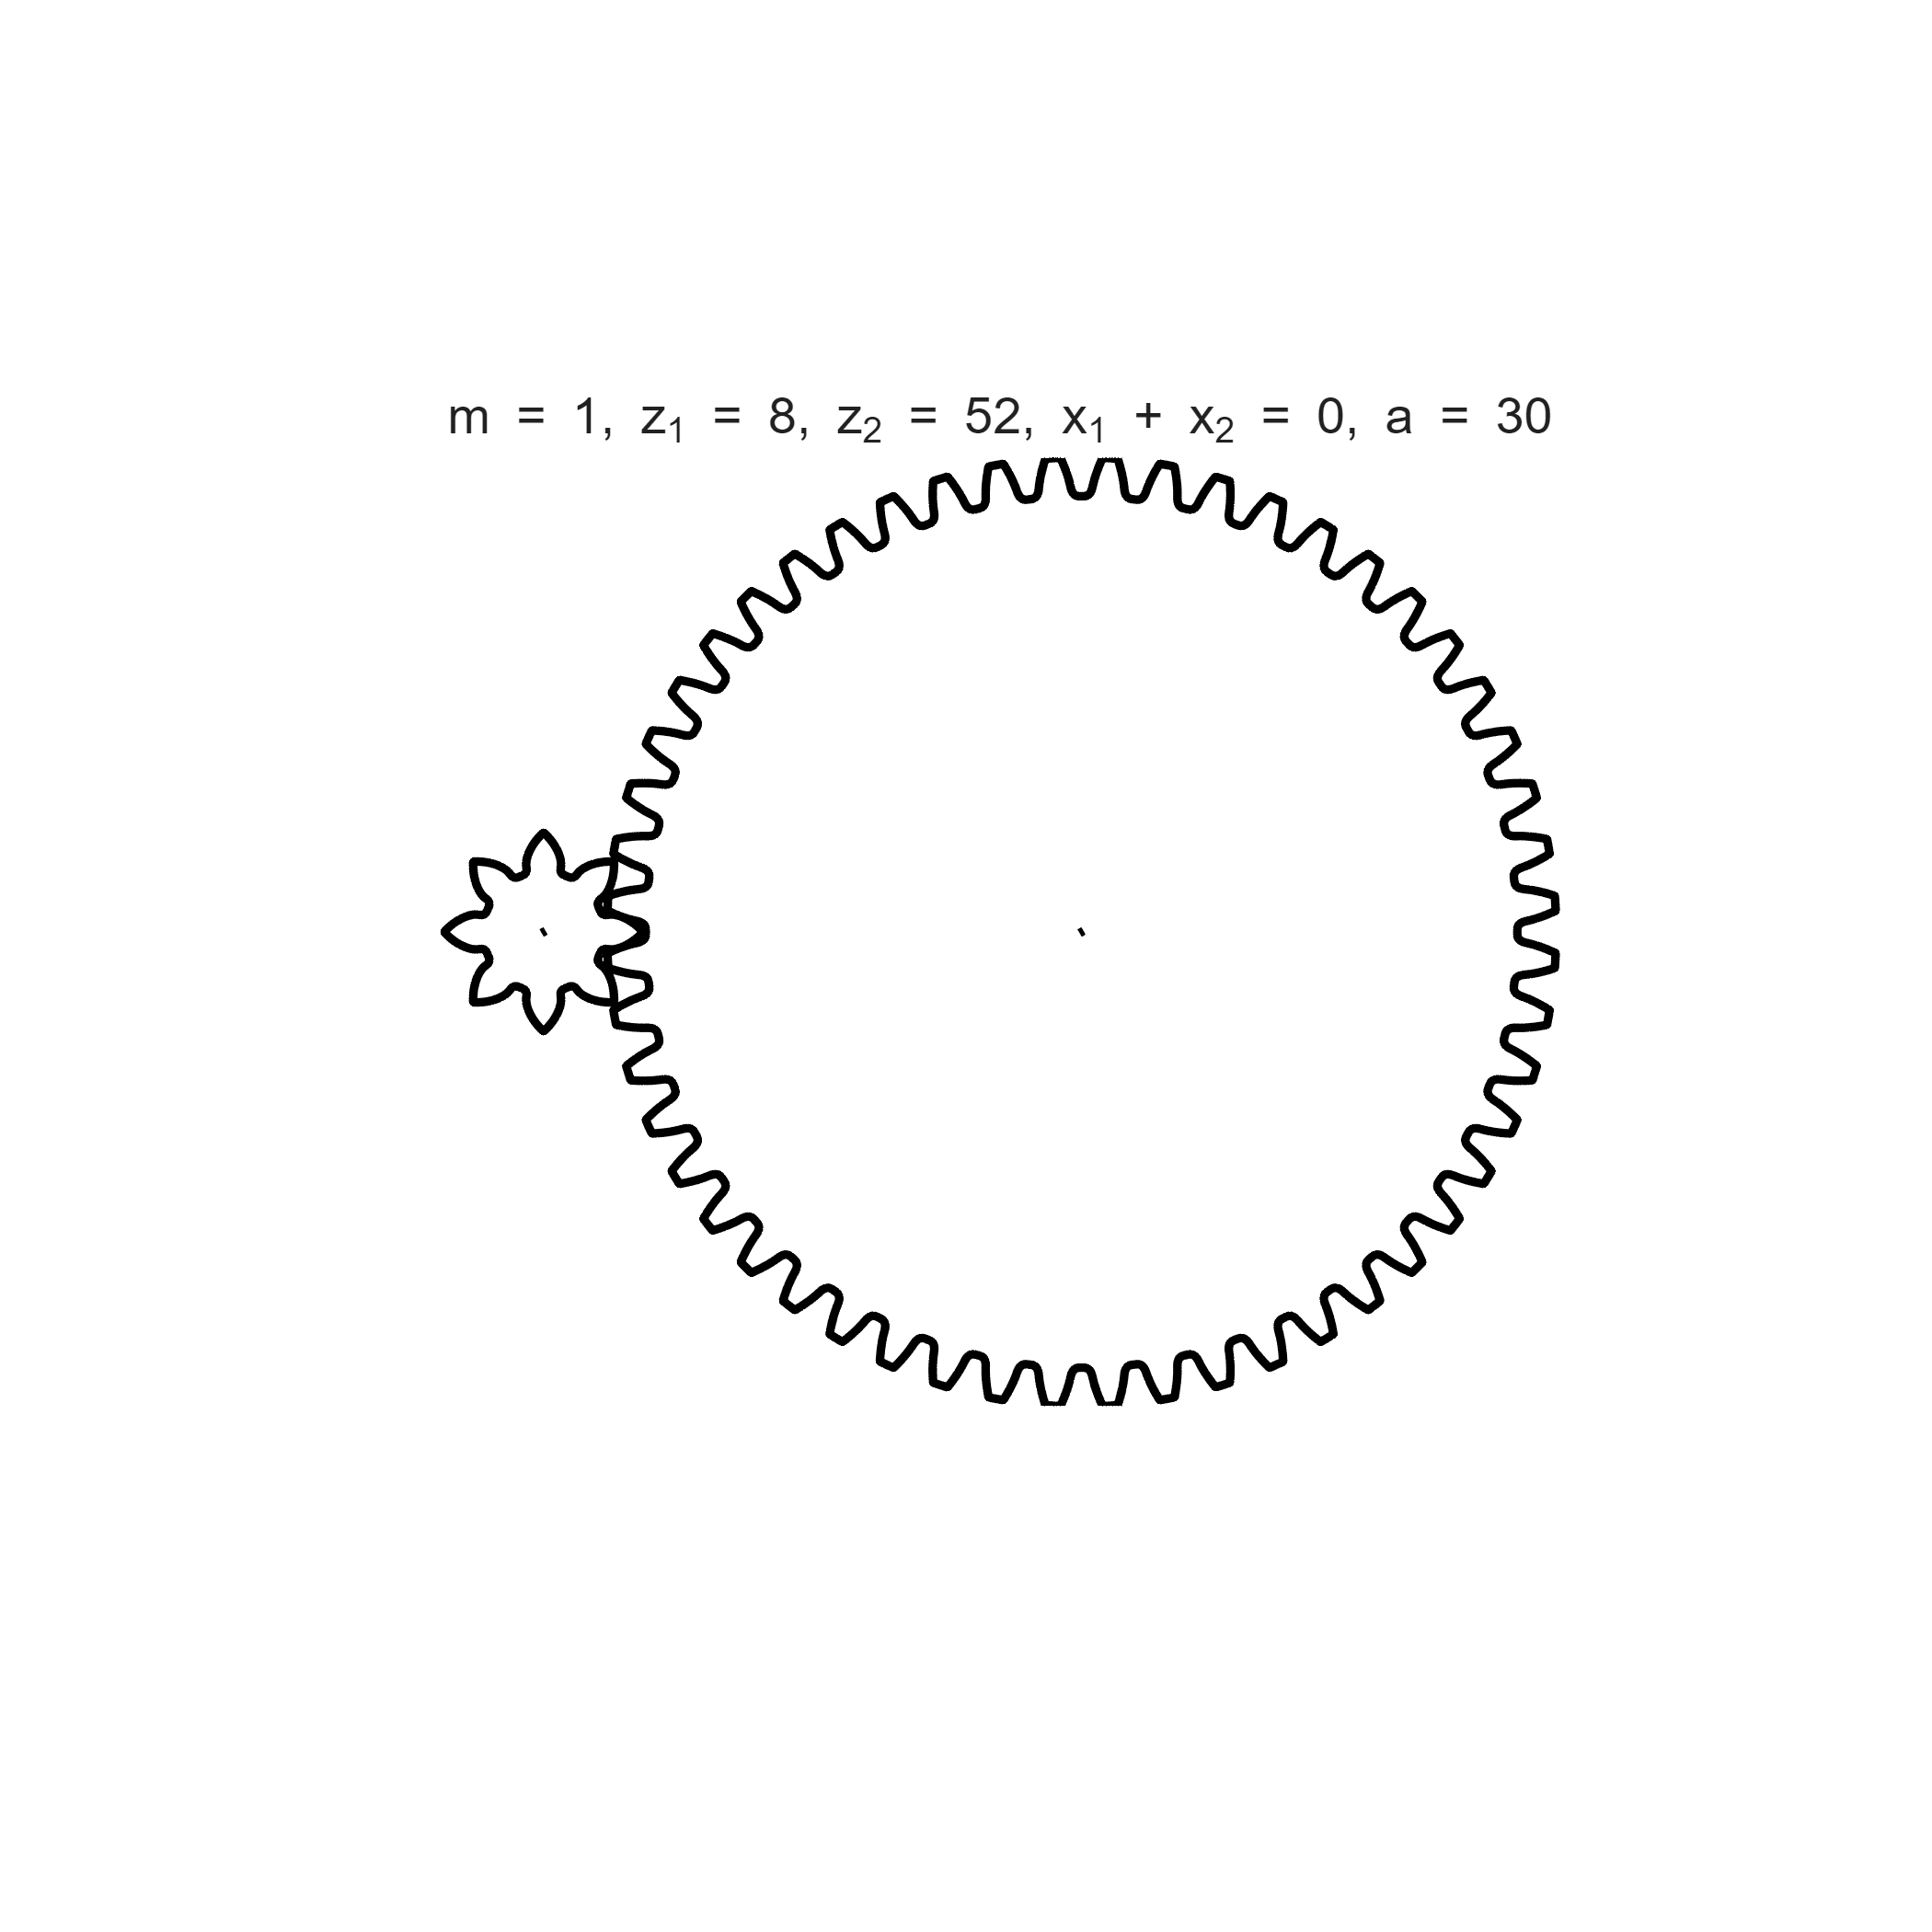

% set profile shift
G1.x = G1.xmin;
G2.x = -G1.xmin;
plot(GM)

print(GM)


Gears in mesh
                               Number of teeth:           8          52
                                        Module:            1.0000       mm
                       Standard pressure angle:           20.0000       
                           Tip tooth clearance:            0.1670       mm
                               Center distance:           30.0000       
                    Tip shortening coefficient:      1.0000      1.0000
                        Working pressure angle:           20.0000       
         Sum of the profile shift coefficients:            0.0000       
                    Profile shift coefficients:      0.5321     -0.5321
Calculated parameters
               Reference pitch circle diameter:      8.0000     52.0000 mm
                 Working pitch circle diameter:      8.0000     52.0000 mm
                      Addendum circle diameter:     11.0642     52.9358 mm
                      Dedendum circle diameter:      6.7302     48.6018 mm
     

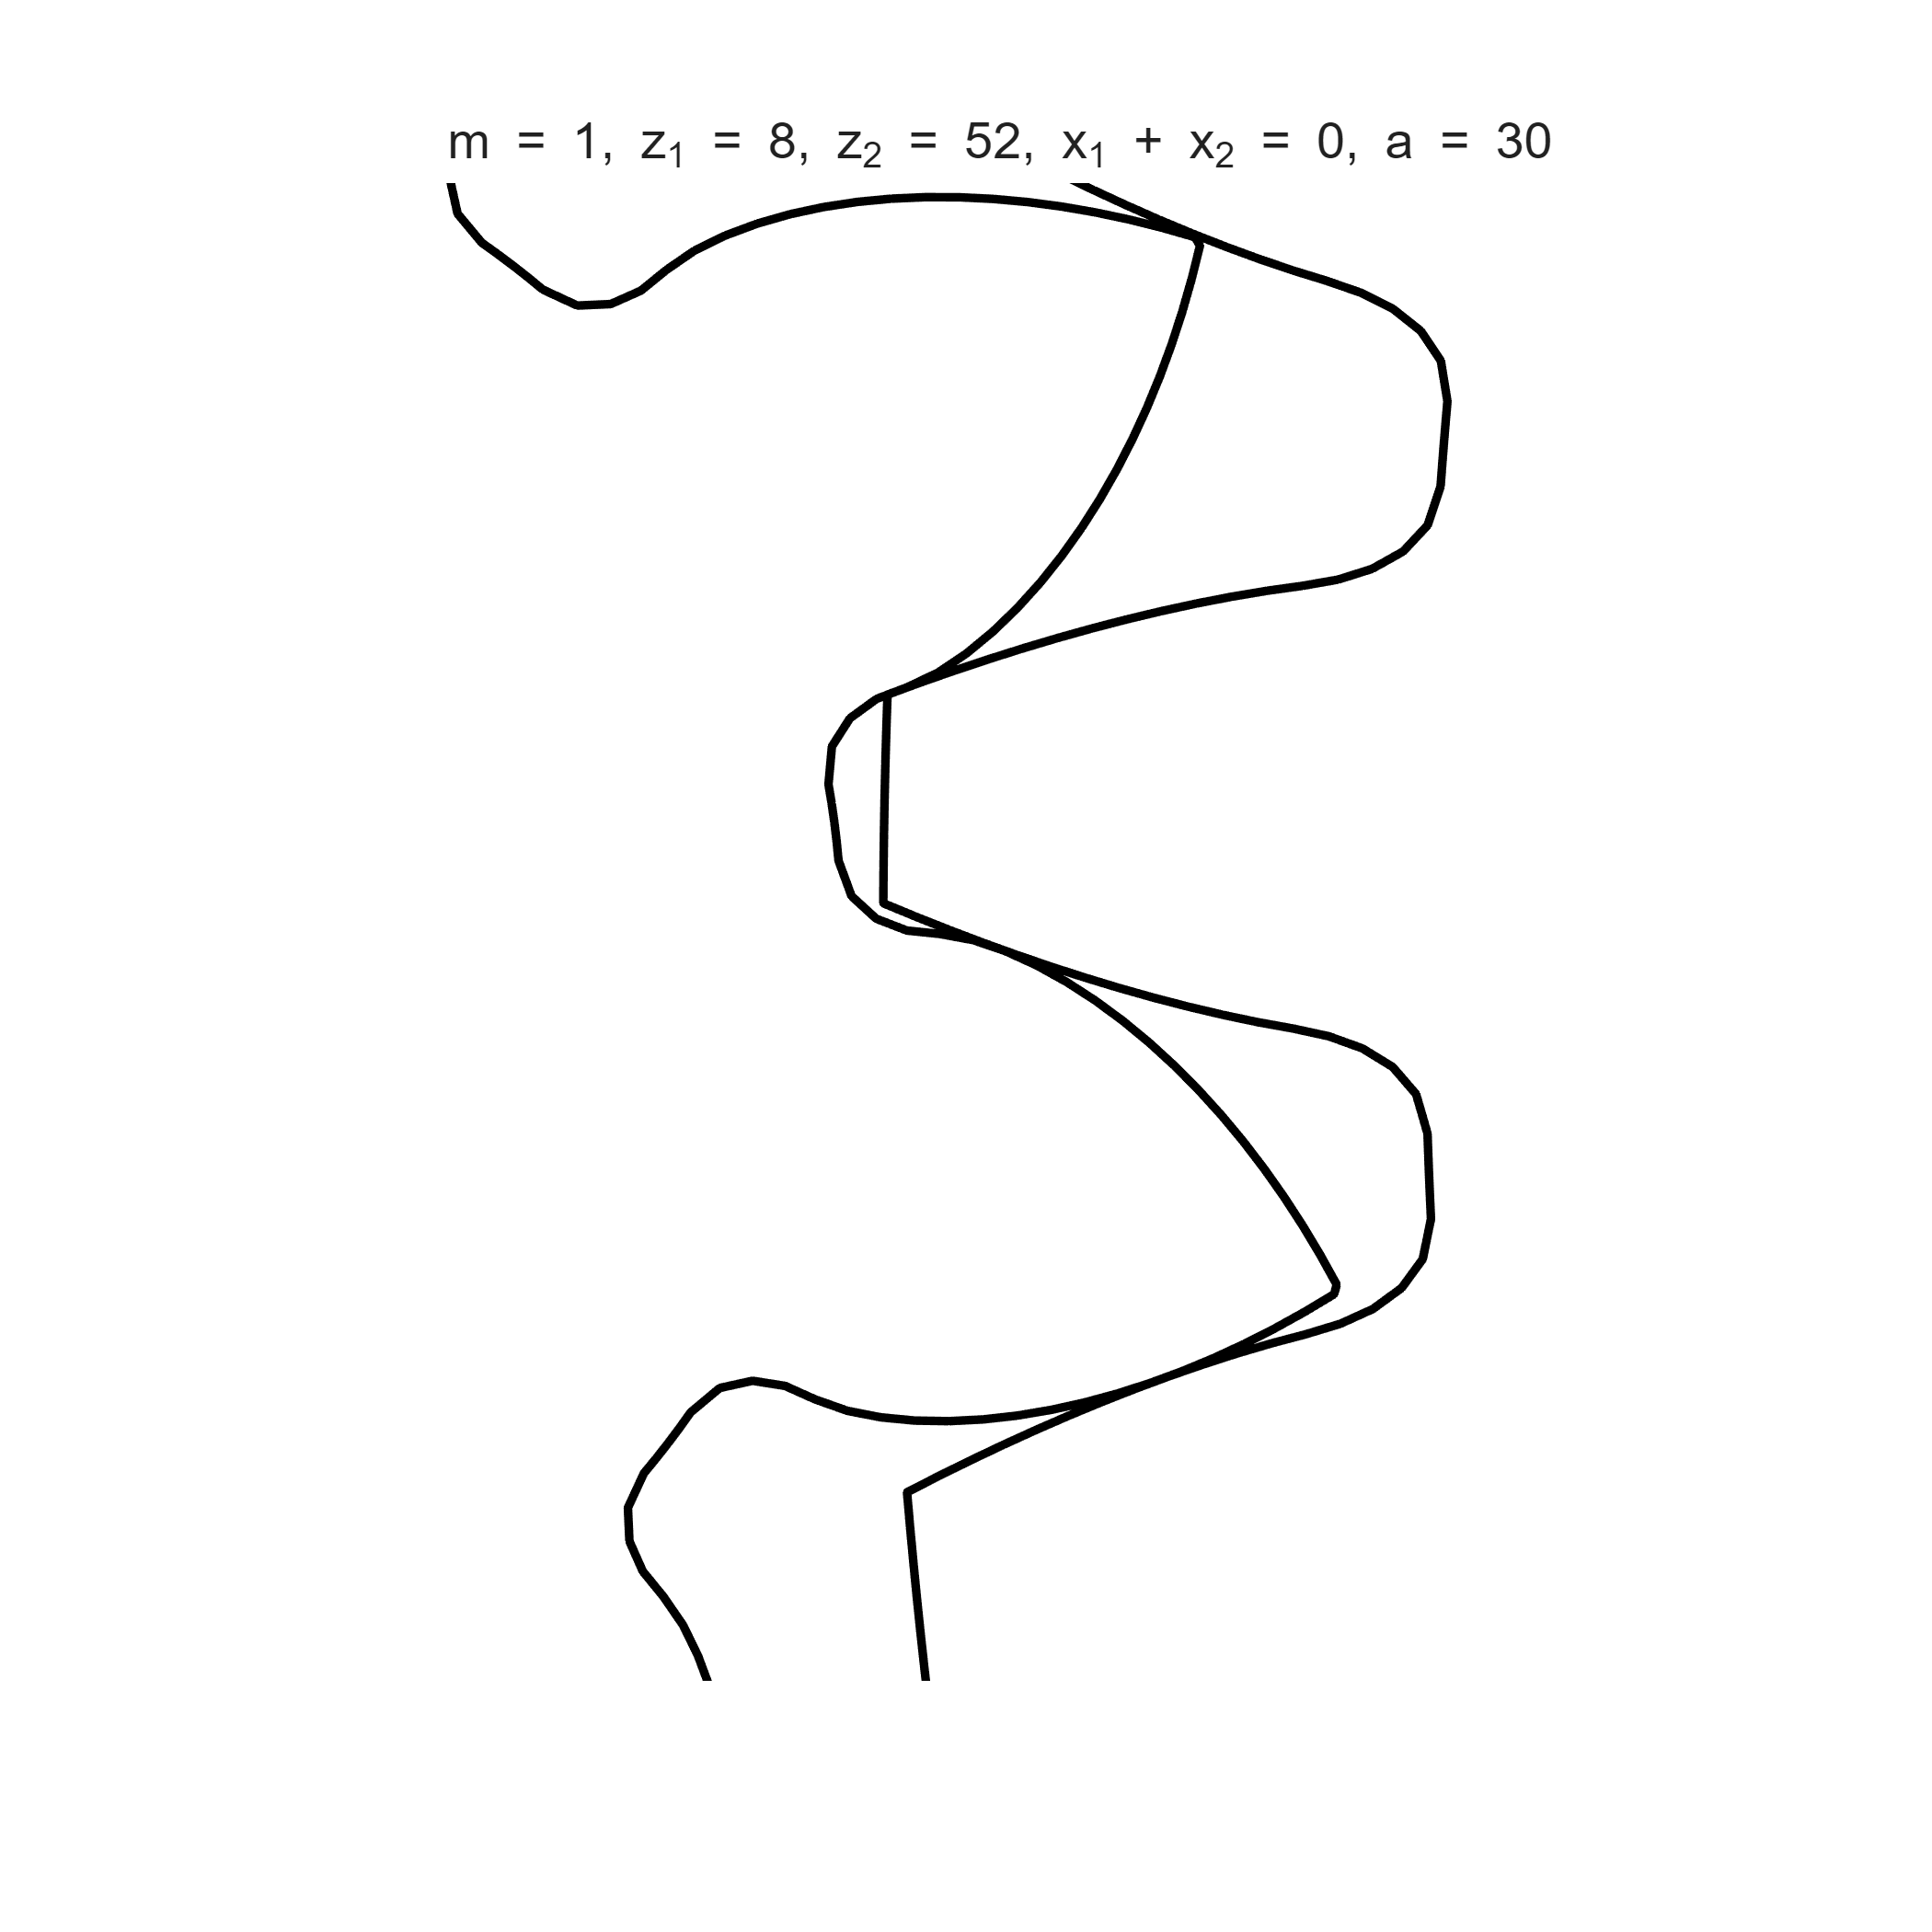


% zoom contact zone within 3 module and rotate gear 1 by 30 deg
plot(GM,'th1',30,'zoom',3)

print(GM)


Gears in mesh
                               Number of teeth:           8          52
                                        Module:            1.0000       mm
                       Standard pressure angle:           20.0000       
                           Tip tooth clearance:            0.1670       mm
                               Center distance:           30.0000       
                    Tip shortening coefficient:      1.0000      1.0000
                        Working pressure angle:           20.0000       
         Sum of the profile shift coefficients:            0.0000       
                    Profile shift coefficients:      0.5321     -0.5321
Calculated parameters
               Reference pitch circle diameter:      8.0000     52.0000 mm
                 Working pitch circle diameter:      8.0000     52.0000 mm
                      Addendum circle diameter:     11.0642     52.9358 mm
                      Dedendum circle diameter:      6.7302     48.6018 mm
     

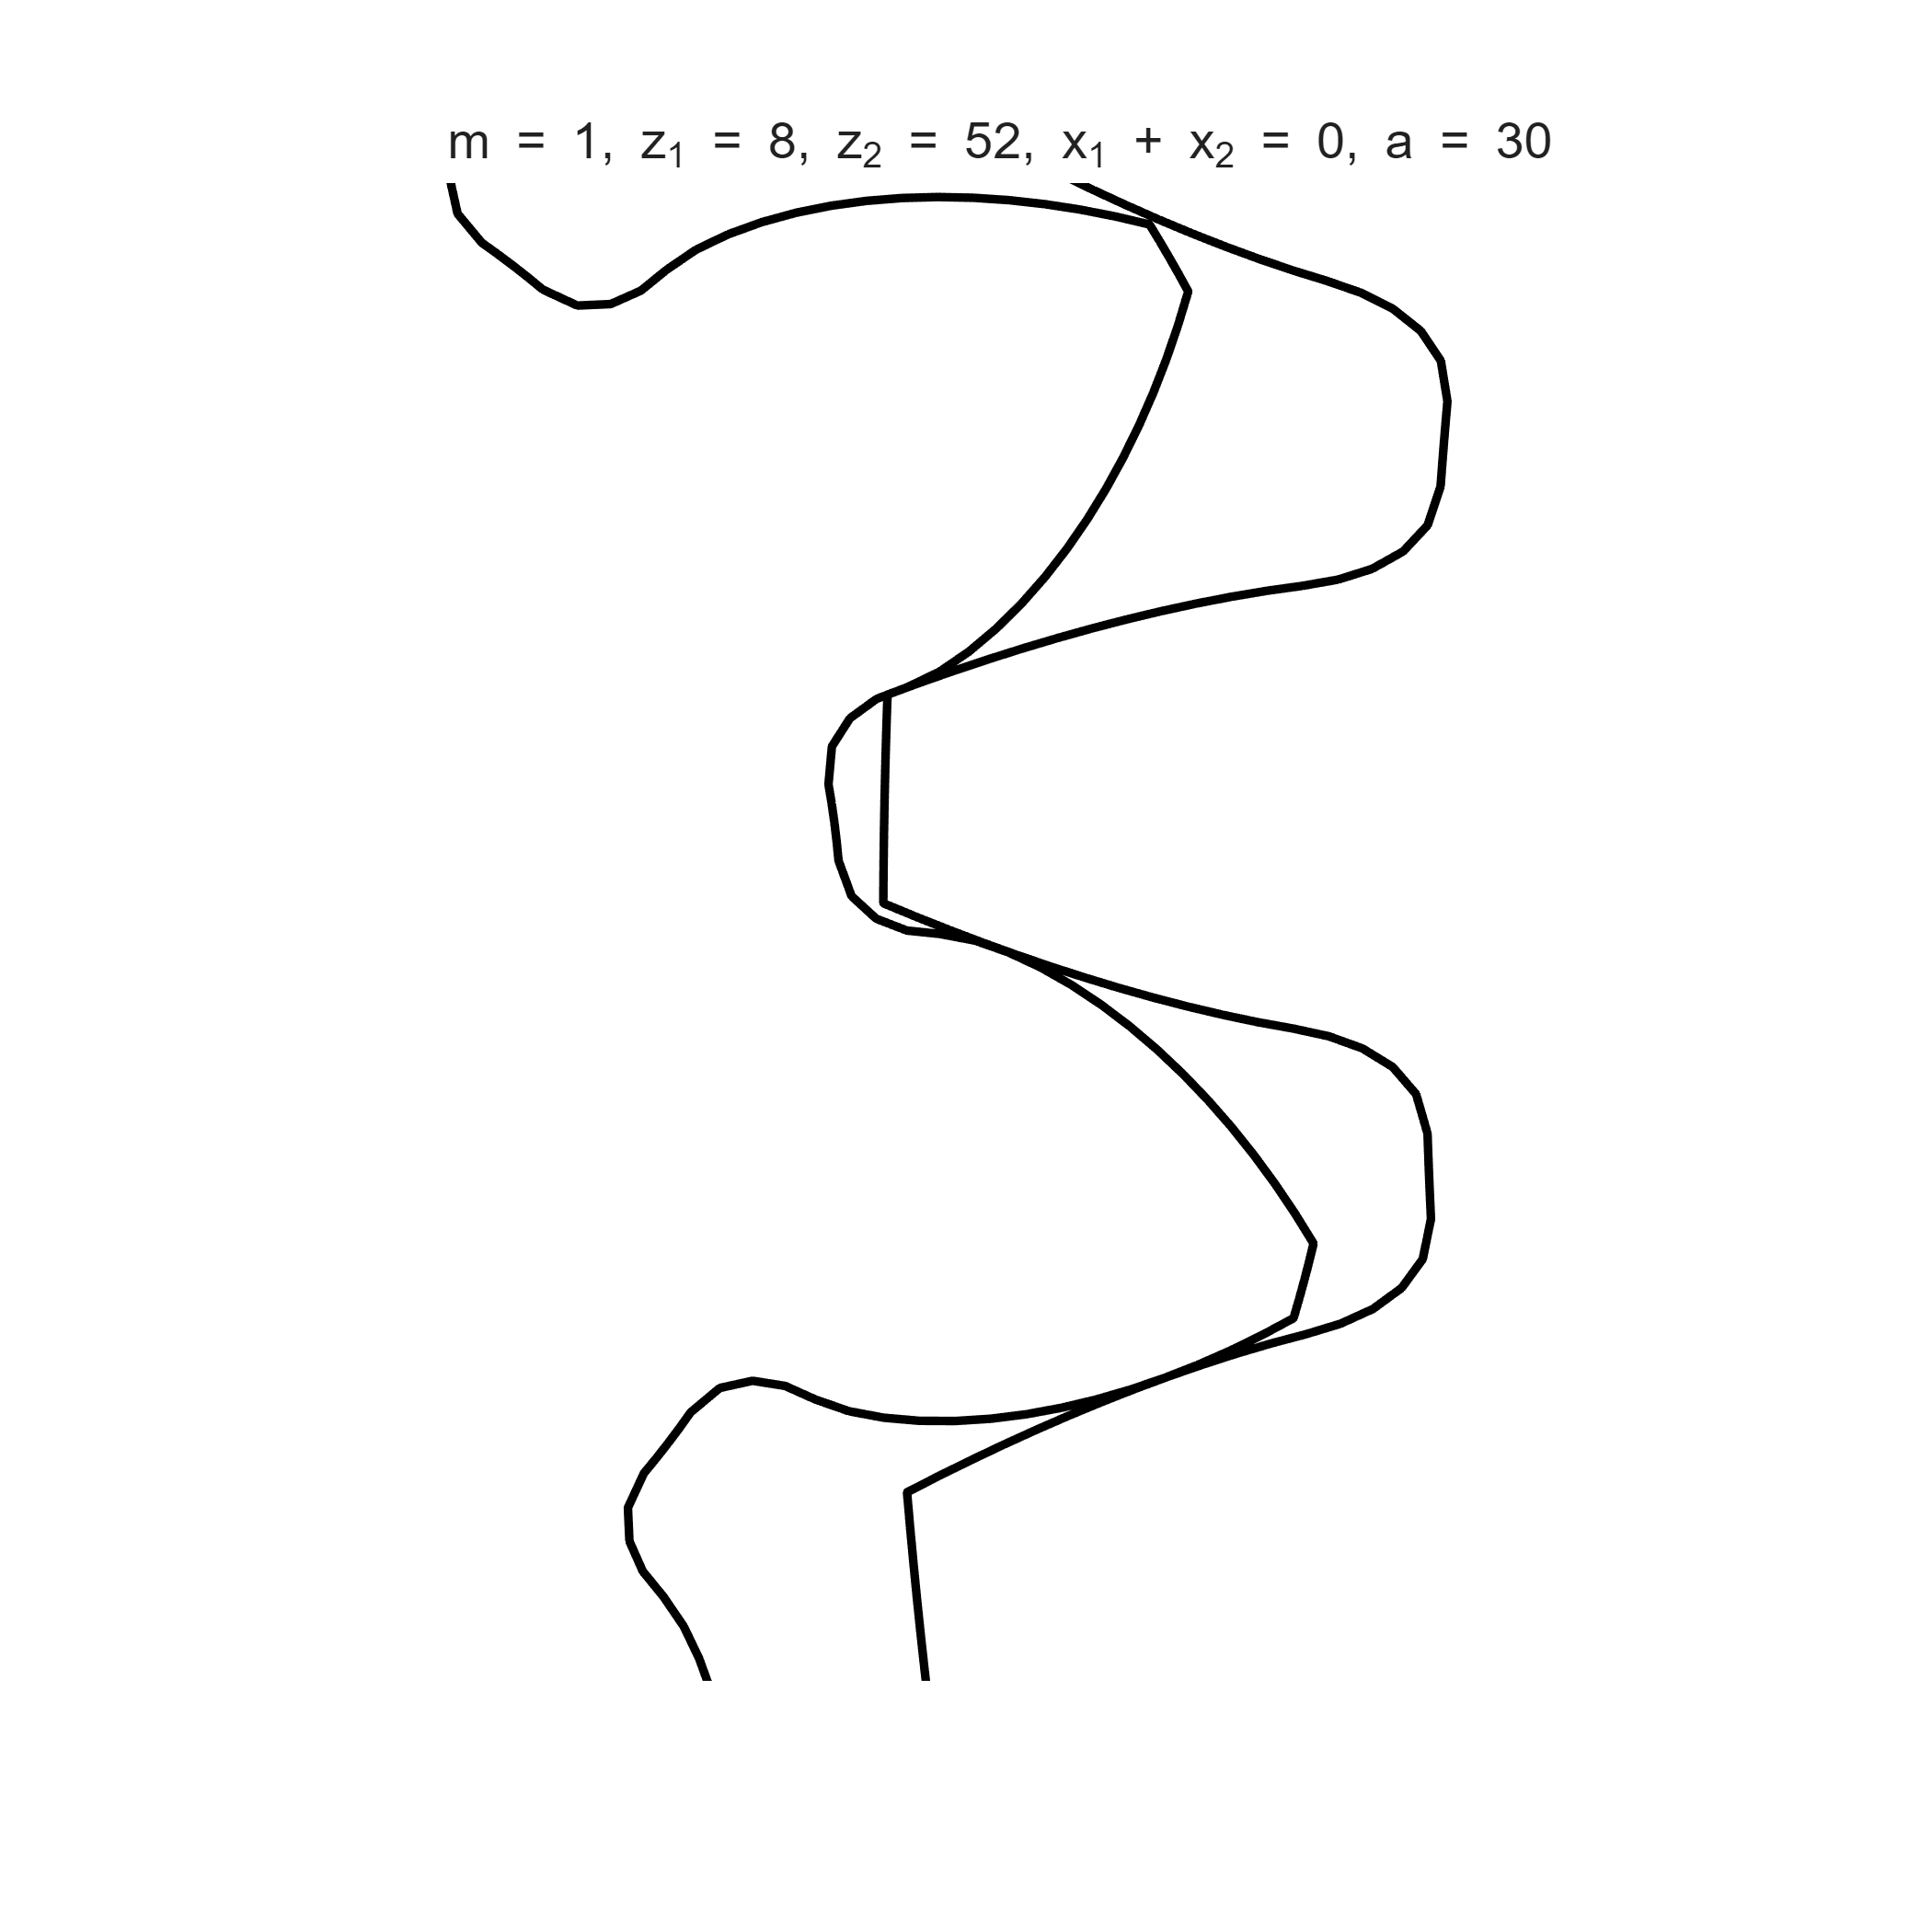

% set u
G1.u = 0.87;
% zoom contact zone within 3 module and rotate gear 1 by 30 deg
plot(GM,'th1',30,'zoom',3)

print(GM)


Gears in mesh
                               Number of teeth:           8          52
                                        Module:            1.0000       mm
                       Standard pressure angle:           20.0000       
                           Tip tooth clearance:            0.1670       mm
                               Center distance:           30.0000       
                    Tip shortening coefficient:      0.8700      1.0000
                        Working pressure angle:           20.0000       
         Sum of the profile shift coefficients:            0.0000       
                    Profile shift coefficients:      0.5321     -0.5321
Calculated parameters
               Reference pitch circle diameter:      8.0000     52.0000 mm
                 Working pitch circle diameter:      8.0000     52.0000 mm
                      Addendum circle diameter:     10.8042     52.9358 mm
                      Dedendum circle diameter:      6.7302     48.6018 mm
     